# PART 4: Path planning(2D)

close all
clear all
clc 

## 2D  planning Example

### Setup the 2D map

% define map size
max_x = 10;
max_y = 10;
map = zeros(max_x, max_y);

% generate random obstacles
obs_per = 0.3;
for x = 1:max_x
    for y = 1:max_y
        if rand < obs_per
            map(x, y) = 1;
        end
    end
end

% define the starting and end position
start = [1, 1];
end_ = [10, 10];
map(start(1), start(2)) = 0;
map(end_(1), end_(2)) = 0;

### Draw the map

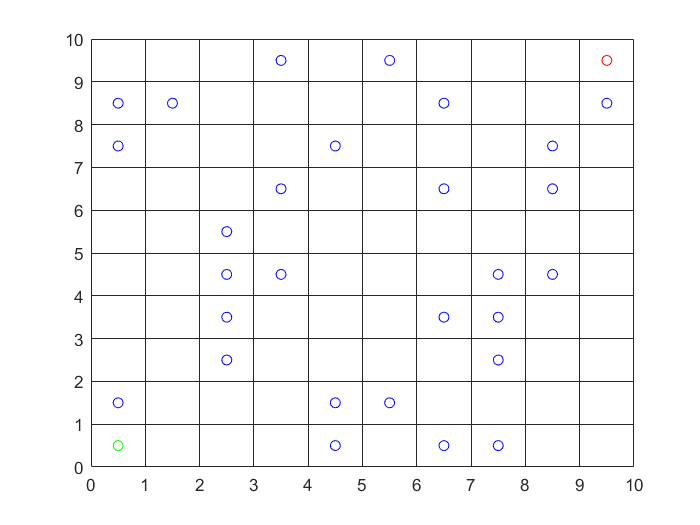

hold off
figure(1)
hold on

% Mark the obstacles with blue
for x = 1:max_x
    for y = 1:max_y
        if map(x, y) == 1
            scatter(x-0.5, y-0.5,[], "blue")
        end
    end
end

% Mark the start with green
scatter(start(1)-0.5, start(2)-0.5, [], "green")
hold on
% Mark the end with red
scatter(end_(1)-0.5, end_(2)-0.5, [], [1, 0, 0])
hold on

%Set the axes
axis([0 max_x 0 max_y])
% Make the grid lines more visible
ax = gca;
ax.GridAlpha = 1.0;
grid on
set(gca, 'xtick', [0:1:max_x])
set(gca, 'ytick', [0:1:max_y])
set(gcf,'Visible','on')

### Running Greedy best-first search

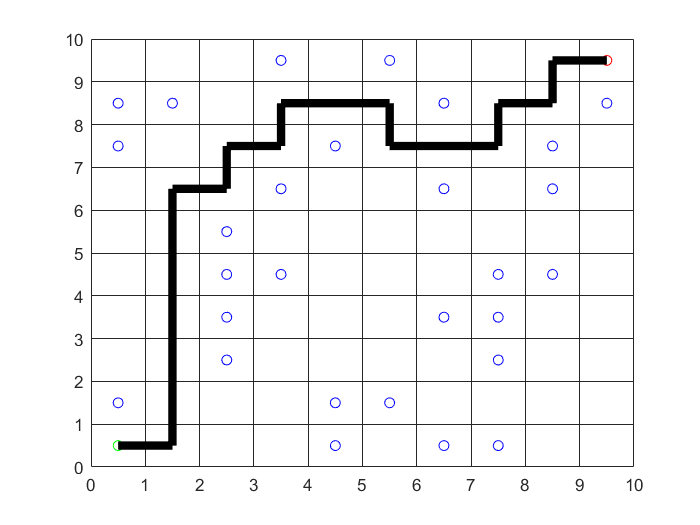

% Run the algorithm to obtain the route
route = greedy2D(map, start, end_); % greedy_2d

% Draw the route
pause on
% route = [x1, y1;
%          x2, y2; ...]
for i = 2:length(route)
    plot([route(i-1, 1)-0.5, route(i, 1)-0.5], ...
         [route(i-1, 2)-0.5, route(i, 2)-0.5], ...
         'Color',[0,0,0], 'LineWidth',5)
    hold on
    pause(0.1)
%     route(i,:);
end

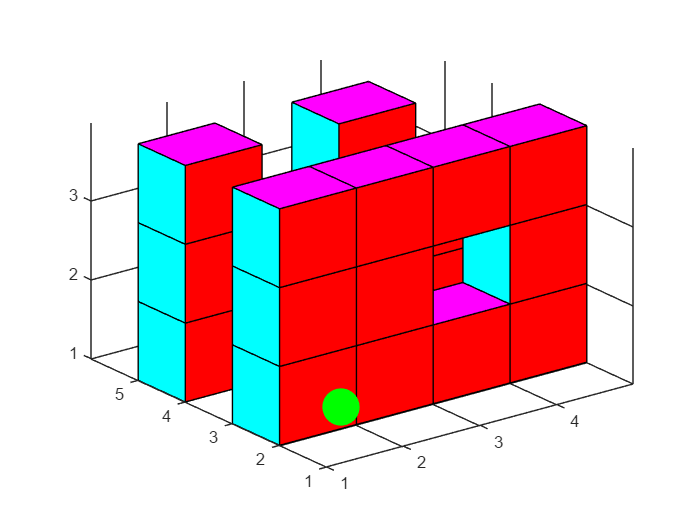

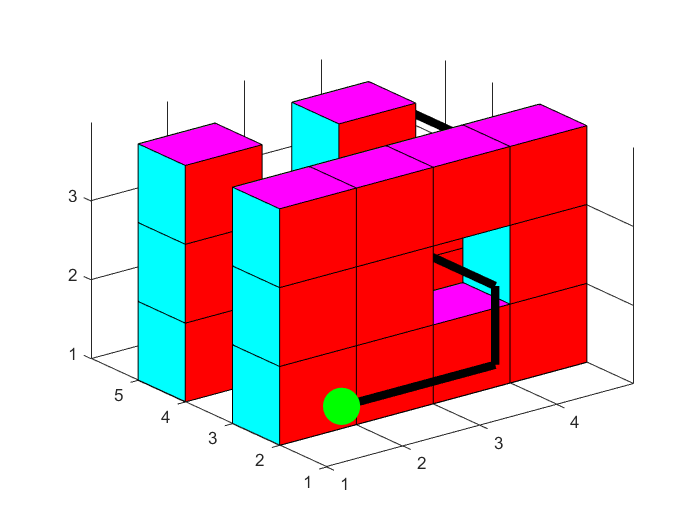

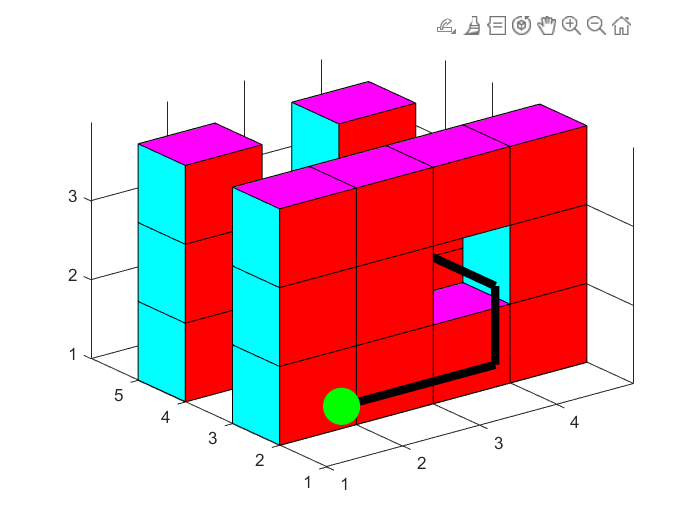

set(gcf,'Visible','on')